%----------------------------------------------------------------------
%Name : Sumit Patidar
%Roll no: B15237
%Task : Program to compute DFT and IDFT
%----------------------------------------------------------------------

close all;
clear;
clc;

%take sequence as an input 
%I am assuming sequence starts from n = 1
x1 = input('enter the sequence x1: '); %example input = [1 2 3 4 5]
x1_length = length(x1);
n1 = 0:1:x1_length - 1;
%plot sequence x1
p1 = subplot(3,1,1);
stem(n1, x1, 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('x_1[n] sequence');
hold on;

%computing N point DFT
N = input('NDFT: ');
X = zeros(1, N);

%pad zeros if N > length of x[n]
if (N > x1_length)
    x1 = [x1 zeros(1,N - x1_length)];
end 

%start DFT algorithm
for k = 0:N - 1
    for n = 0:N-1
       X(k+1) = X(k+1) + x1(n+1)*exp(-2*pi*k*1i*n/N);
    end
end


%plot DFT
p2 = subplot(3,1,2);
stem([0:N-1], abs(X), 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('DFT X[k]');
hold on;


%compute IDFT
Xi = X;
Ni = input('IDFT: ')

Ni = 9

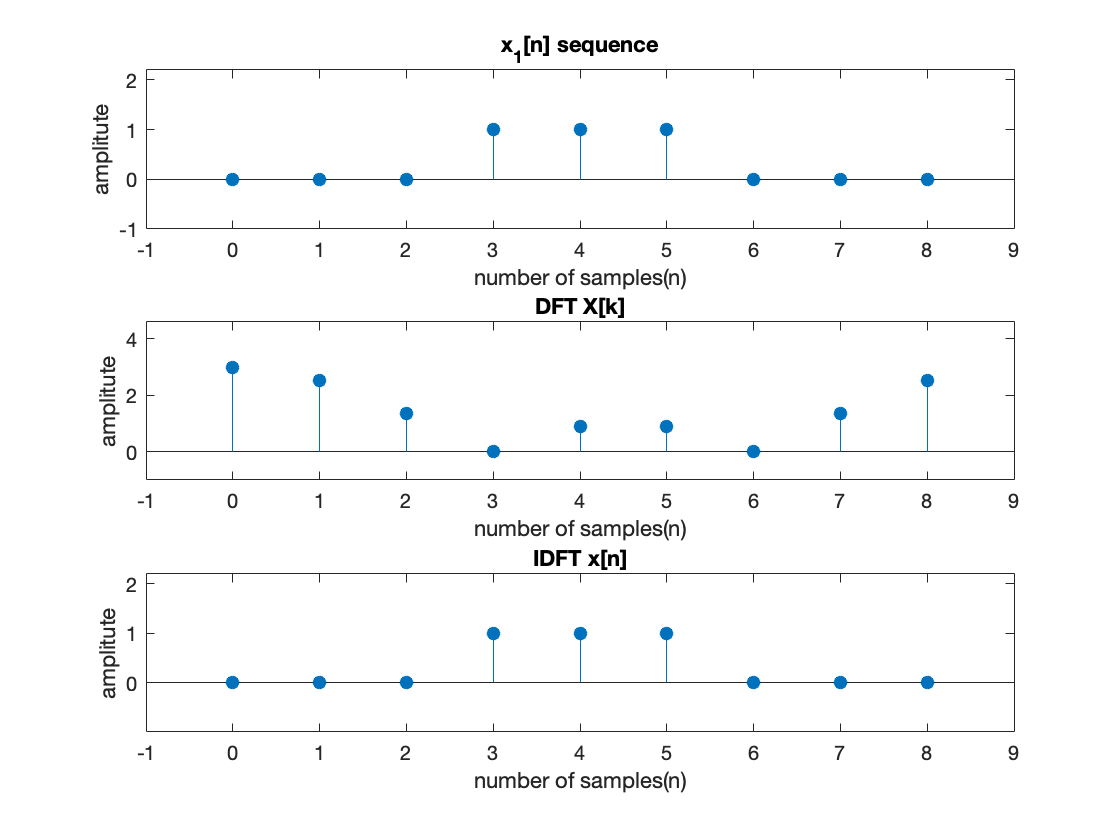

xi = zeros(1, Ni);

%pad zeros if N > length of x[n]
if (Ni > length(Xi))
    Xi = [Xi zeros(1,Ni - length(Xi))];
end 

%start IDFT algorithm
for n2 = 0:Ni-1
    for k2 = 0:Ni-1
        xi(n2+1) = xi(n2+1) + Xi(k2+1)*exp(2*pi*1i*k2*n2/Ni);
    end
end
xi = xi/Ni;

%plot IDFT
p3 = subplot(3,1,3);
stem([0:Ni-1], abs(xi), 'filled');
xlabel('number of samples(n)');
ylabel('amplitute');
title('IDFT x[n]');
hold on;

%setting axis limits to visualize better
axis(p1, [-1  x1_length min(abs(x1))*1.2-1 max(abs(x1))*1.2+1]);
axis(p2, [-1  N min(abs(X))*1.2-1 max(abs(X))*1.2+1]);
axis(p3, [-1  Ni min(abs(xi))*1.2-1 max(abs(xi))*1.2+1]);


display(X);

X =    3.0000 + 0.0000i  -2.3794 - 0.8660i   1.0321 + 0.8660i  -0.0000 - 0.0000i  -0.1527 - 0.8660i  -0.1527 + 0.8660i   0.0000 - 0.0000i   1.0321 - 0.8660i  -2.3794 + 0.8660i


display(xi);

xi =   -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   1.0000 - 0.0000i   1.0000 - 0.0000i   1.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
